"Synthetic Data Generator" by Kambadur Ananthamurthy

This code uses real dF/F data, populates a library of calcium events, and then creates a synthetic dataset based on the control parameters.

Here is a list of functions or other scripts called within this main script:

- setupSyntheticDataParameters.m

- findConsecutiveOnes.m

- syntheticDataMaker.m

- developQ.m

- generateNoise.m

- selectFrameIndex.m

- plotdFbyF.m

- getETH.m

Please ensure that you have acess to all of them before proceeding.

tic
close all
clear

addpath(genpath('/Users/ananth/Documents/MATLAB/CustomFunctions')) % my custom functions
addpath(genpath('/Users/ananth/Documents/MATLAB/ImagingAnalysis')) % Additional functions
addpath(genpath('/Users/ananth/Documents/MATLAB/ImagingAnalysis/Suite2P-ananth'))

## Operations

This section provides some operational controls.

%ops0.fig             = 1;
ops0.saveData        = 1;

figureDetails = compileFigureDetails(16, 2, 10, 0.5, 'jet'); %(fontSize, lineWidth, markerSize, transparency, colorMap)
%ops0.onlyProbeTrials = 0

## Real Dataset Details

Here, one must provide details of the real dataset to be referenced while making the synthetic data. The code uses some of these parameters to locate the file containing the real dF/F data, while the other parameters are important for functions and plotting. The structure of this section is directly as is required for the Suite-2P analysis pipeline.

It is crucial to use dF/F values rather than the raw fluorescence traces, since only then can the different calcium events be comparable.

make_db

fprintf('Reference Dataset - %s_%i_%i | Date: %s\n', db.mouseName, ...
    db.sessionType, ...
    db.session, ...
    db.date)

Reference Dataset - M26_5_4 | Date: 20180514


## Load dF/F

We then load the real processed data based on the reference dataset.

saveDirec = '/Users/ananth/Desktop/Work/Analysis/Imaging/';
saveFolder = [saveDirec db.mouseName '/' db.date '/'];

%Load processed data (processed dfbf for dataset/session)
realProcessedData = load([saveFolder db.mouseName '_' db.date '.mat']);
nCells = size(realProcessedData.dfbf, 1);
nTrials = size(realProcessedData.dfbf, 2);
nFrames = size(realProcessedData.dfbf, 3);
fprintf('Total cells: %i\n', nCells)

Total cells: 135


## Synthetic Data Control Parameters

Here, one must provide all the control parameters required to generate the synthetic data. These can be found in a header-like file called setupSyntheticDataParameters.m. This sort of implementation ensures minimal (if any) change to this main script, while changing parameters.

setupSyntheticDataParameters

## Curate Calcium Event Library

This next section of code ensures that we have a working library of calcium events.

%Cell specific curation of the calcium event library
%Check to see if the library exits
if isfile([saveFolder db.mouseName '_' db.date '_eventLibrary_2D.mat'])
    disp('Loading existing event library ...')
    load([saveFolder db.mouseName '_' db.date '_eventLibrary_2D.mat'])
    disp('... done!')
else
    %Use real 2D data
    cellMean = zeros(nCells, 1);
    cellStddev = zeros(nCells, 1);
    binaryData = zeros(nCells, 1);
    
    disp('Basic scan for calcium events ...')
    
    %Preallocation
    s.nEvents = 0;
    s.eventStartIndices = [];
    s.eventWidths = [];
    eventLibrary_2D = repmat(s, 1, nCells);
    clear s
    
    for cell = 1:nCells
        sampledCellActivity = squeeze(realProcessedData.dfbf_2D(cell, :));
        cellMean(cell) = mean(sampledCellActivity);
        cellStddev(cell) = std(sampledCellActivity);
        logicalIndices = sampledCellActivity > (cellMean(cell) + 2* cellStddev(cell));
        binaryData(logicalIndices, 1) = 1;
        minNumberOf1s = 3;
        [nEvents, StartIndices, Width] = findConsecutiveOnes(binaryData, minNumberOf1s);
        eventLibrary_2D(cell).nEvents = nEvents;
        eventLibrary_2D(cell).eventStartIndices = StartIndices;
        eventLibrary_2D(cell).eventWidths = Width;
        
        clear binaryData
        clear Events
        clear StartIndices
        clear Lengths
    end
    save([saveFolder db.mouseName '_' db.date '_eventLibrary_2D.mat'], 'eventLibrary_2D')
    disp('... library curated and saved!')
end

Loading existing event library ...


... done!


## Make Synthetic Data

This is business end. We call the syntheticDataMaker function with the control parameters passed in as arguments.

%for i = 1:length(sdcp)
%i = 1;
i = length(sdcp);
fprintf('Currently running control parameter set: %i\n', i)

Currently running control parameter set: 1


sdo = syntheticDataMaker(db, realProcessedData.dfbf_2D, eventLibrary_2D, sdcp(i));

Creating synthetic data ...
... Number of Putative Time Cells: 135
... done!


%Run specifics
scurr = rng;
sdo.scurr = scurr; %Saves current status of randomseed
sdo.endTime = datestr(now,'mm-dd-yyyy_HH-MM');

## Quality metric (Q)

Next, we develop a quality metric "Q', to assign a reliability score to every cell in the synthetic dataset.


$$Q=\text{Hit}\text{ }\text{Trial}\text{ }\text{Ratio}\ast \exp \left(-1\ast \left(\frac{\mathrm{Max}\text{ }\mathrm{Noise}}{\mathrm{Max}\text{ }\mathrm{Signal}}+\text{ }\frac{1}{\mathrm{nFrames}\text{ }\mathrm{per}\text{ }\mathrm{Trial}}\ast \left(\frac{\mathrm{Max}\text{ }\mathrm{Event}\text{ }\mathrm{Width}+\mathrm{Min}\text{ }\mathrm{Event}\text{ }\mathrm{Width}}{2}+\mathrm{ImprecisionFWHM}\right)\right)\right)$$


Here, the Hit Trial Percent and the Actual Event Widths are cell specific, while the other controls are fixed for every cell (specified as synthetic data control parameters).

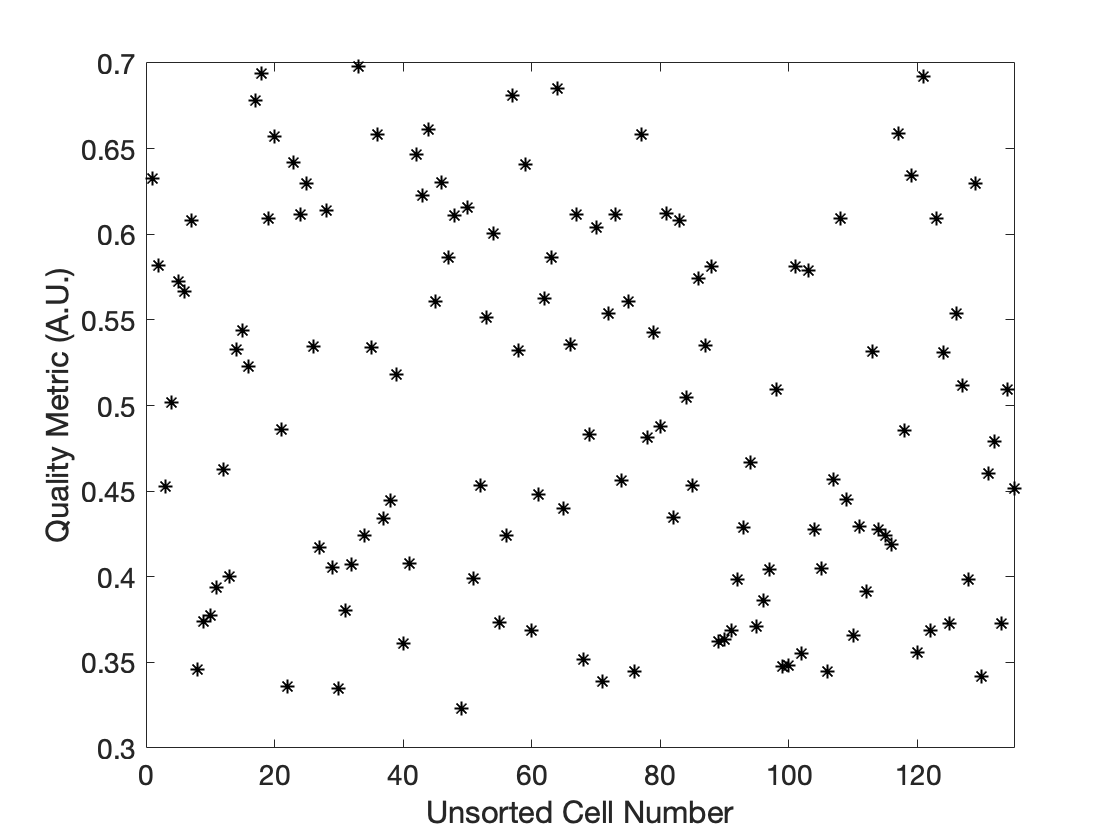

params4Q.nTotalCells = sdo.nTotalCells;
params4Q.hitTrialPercent = sdo.hitTrialPercent;
params4Q.noisePercent = sdcp(i).noisePercent;
params4Q.eventAmplificationFactor = sdcp(i).eventAmplificationFactor;
params4Q.maxSignal = sdo.maxSignal;
params4Q.actualEventWidth = sdo.actualEventWidth;
params4Q.imprecisionFWHM = sdcp(i).imprecisionFWHM;
params4Q.nTotalFrames = size(sdo.syntheticDATA, 3);

sdo.Q = developQ(params4Q);

figure(1)
clf
plot(sdo.Q, 'k*')
xlim([0 nCells])
xlabel('Unsorted Cell Number', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
ylabel('Quality Metric (A.U.)', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize-2)

print(['/Users/ananth/Desktop/figs/syntheticData/synthData' ...
    '_Q_' ...
    db.mouseName '_' num2str(db.sessionType) '_' num2str(db.session), ...
    '_' sdo.endTime], ...
    '-djpeg')

## Plotting the Synthetic Dataset

We can now visualize the synthetic dataset along with checks to ensure the control parameters are working as expected

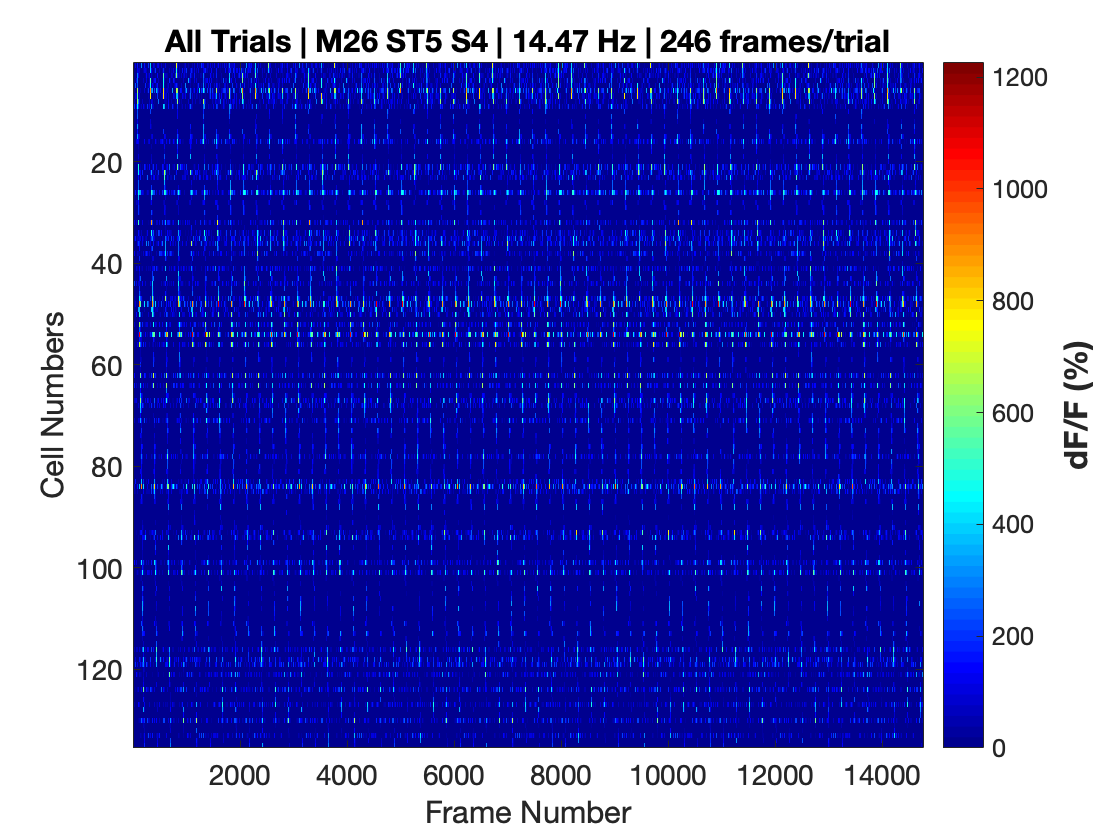

% All trials
figure(2)
clf
plotdFbyF(db, sdo.syntheticDATA_2D, 'All Trials', 'Frame Number', 'Cell Numbers', figureDetails, 0)
colormap(figureDetails.colorMap)

print(['/Users/ananth/Desktop/figs/syntheticData/synthData' ...
    '-' ...
    db.mouseName '_' num2str(db.sessionType) '_' num2str(db.session), ...
    '_' sdo.endTime], ...
    '-djpeg')

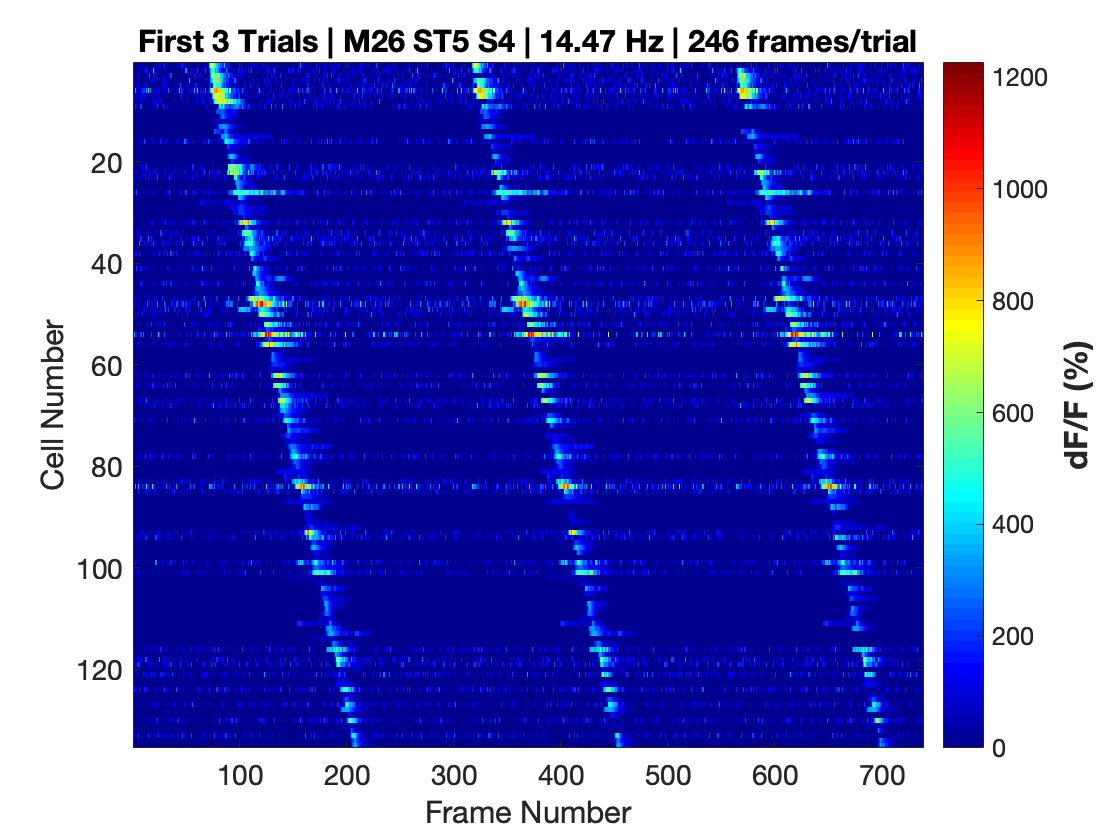

% Only first 3 trials
fig3 = figure(3);
%set(fig2,'Position',[300,300,1000,800])
clf
plotdFbyF(db, sdo.syntheticDATA_2D(:,1:(3*db.nFrames)), 'First 3 Trials', 'Frame Number', 'Cell Number', figureDetails, 0)
colormap(figureDetails.colorMap)

print(['/Users/ananth/Desktop/figs/syntheticData/synthData' ...
    '_first3trials_' ...
    db.mouseName '_' num2str(db.sessionType) '_' num2str(db.session), ...
    '_' sdo.endTime], ...
    '-djpeg')

## Time Vectors

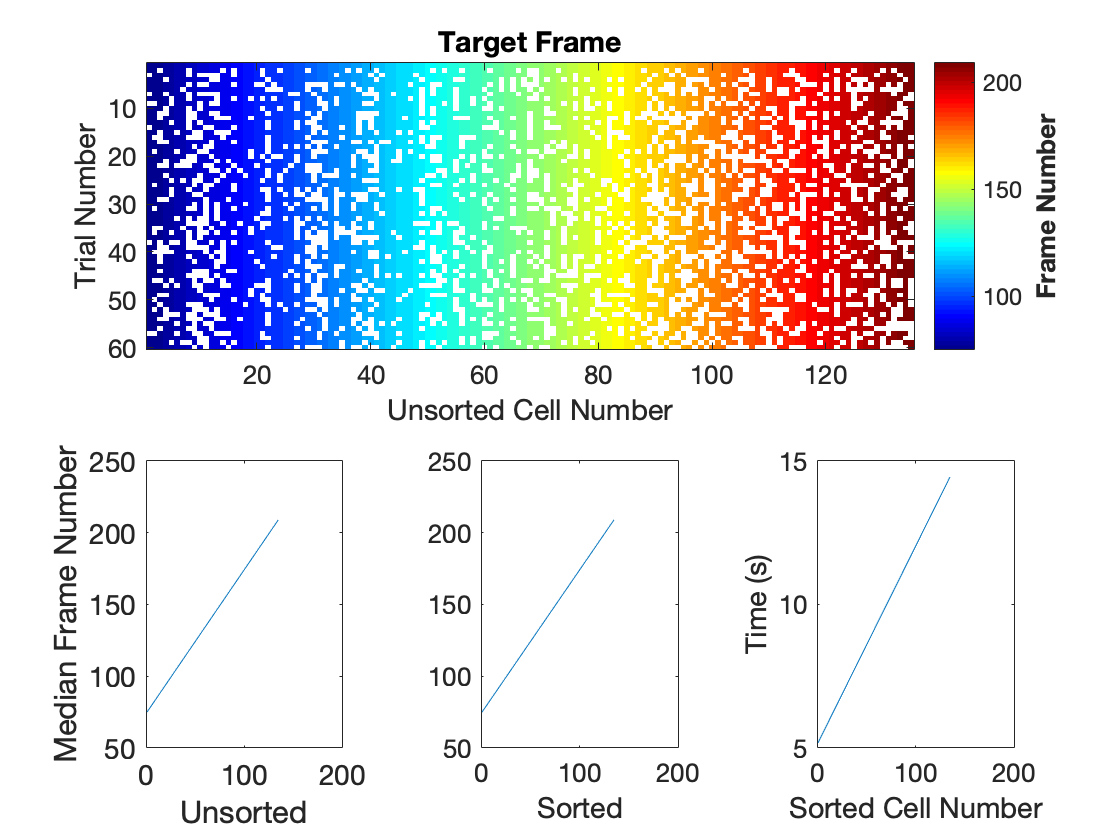

timeMatrix = sdo.frameIndex;
figure(4)
clf
subplot(2, 8, 1:8)
%imagesc(timeMatrix(sdo.ptcList, :)')
X = imagesc(timeMatrix');
set(X,'AlphaData',~isnan(timeMatrix'))
z = colorbar;
ylabel(z,'Frame Number', ...
    'FontSize', figureDetails.fontSize-3, ...
    'FontWeight', 'bold')
colormap('jet')
%caxis([sdcp.startFrame sdcp.endFrame])
title('Target Frame', ...
    'FontSize', figureDetails.fontSize-3, ...
    'FontWeight', 'bold')
xlabel('Unsorted Cell Number', ...
    'FontSize', figureDetails.fontSize-3, ...
    'FontWeight', 'bold')
ylabel('Trial Number', ...
    'FontSize', figureDetails.fontSize-3, ...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize-3)

subplot(2, 8, 9:10)
%plot(mean(timeMatrix(sdo.ptcList, :), 2))
plot(nanmean(timeMatrix, 2))
%xlim([0 length(sdo.ptcList)])
%xlim([0 size(timeMatrix, 1)])
%ylim([0 db.nFrames])
% title('Target Frame', ...
%     'FontSize', figureDetails.fontSize, ...
%     'FontWeight', 'bold')
xlabel('Unsorted', ...
    'FontSize', figureDetails.fontSize-3, ...
    'FontWeight', 'bold')
ylabel('Median Frame Number', ...
    'FontSize', figureDetails.fontSize-3, ...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize-2)

subplot(2, 8, 12:13)
%plot(sort(nanmean(timeMatrix(sdo.ptcList, :), 2)))
plot(sort(nanmean(timeMatrix, 2)))
%xlim([0 length(sdo.ptcList)])
%xlim([0 size(timeMatrix, 1)])
%ylim([0 db.nFrames])
%set(gca,'YTickLabel',[]);
% title('Target Frame', ...
%     'FontSize', figureDetails.fontSize-2, ...
%     'FontWeight', 'bold')
xlabel('Sorted', ...
    'FontSize', figureDetails.fontSize-3, ...
    'FontWeight', 'bold')
% ylabel('Median Frame Number', ...
%     'FontSize', figureDetails.fontSize, ...
%     'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize-3)

subplot(2, 8, 15:16)
%plot(sort(mean(timeMatrix(sdo.ptcList, :), 2) / db.samplingRate))
plot(sort(nanmean(timeMatrix, 2) / db.samplingRate))
%xlim([0 length(sdo.ptcList)])
%xlim([0 size(timeMatrix, 1)])
%ylim([0 db.nFrames])
% title('Target Frame', ...
%     'FontSize', figureDetails.fontSize, ...
%     'FontWeight', 'bold')
xlabel('Sorted Cell Number', ...
    'FontSize', figureDetails.fontSize-3, ...
    'FontWeight', 'bold')
ylabel('Time (s)', ...
    'FontSize', figureDetails.fontSize-3, ...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize-3)

print(['/Users/ananth/Desktop/figs/syntheticData/synthData' ...
    '_frameIndex_' ...
    db.mouseName '_' num2str(db.sessionType) '_' num2str(db.session), ...
    '_' sdo.endTime], ...
    '-djpeg')

## Check - Percent Time Cells, Percent Hit Trials, Event Amplification Factor

sdtc_peaks = nan(nCells, nTrials); % Putative Time Cells
sdoc_peaks = nan(nCells, nTrials); % Other Cells
for cell = 1:nCells
        for trial = 1:nTrials
            if ismember(cell, sdo.ptcList)
                sdtc_peaks(cell, trial) = max(sdo.syntheticDATA(cell, trial, :));
            else
                sdoc_peaks(cell, trial) = max(sdo.syntheticDATA(cell, trial, :));
            end
        end
end
X1 = sum(sdtc_peaks, 2);
X2 = sum(sdoc_peaks, 2);

figure(5)
clf
subplot(2, 6, 1:4)
plot(X1, 'm*')
hold on
plot(X2, 'k*')
hold off
if length(X1) > length(X2)
    xlim([0 length(X1)])
else
    xlim([0 length(X2)])
end
% title('Putative Time Cells vs Other Cells', ...
%     'FontSize', figureDetails.fontSize, ...
%     'FontWeight', 'bold')
xlabel('Cell Number', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
ylabel('Summed Peak Value (dF/F %)', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
legend('Putative Time Cell (PTC)', 'Other Cell (OC)')
set(gca,'FontSize', figureDetails.fontSize-2)

subplot(2, 6, 5)
boxplot(X1, ...
    'Notch','on', ...
    'Labels',{'PTC'}, ...
    'Whisker', 1, ...
    'Color', 'm')
ylim([0 max(X1)])
set(gca,'YTick',0:100:max(X1))
set(gca,'YTickLabel',[])
set(gca,'FontSize', figureDetails.fontSize-2)

subplot(2, 6, 6)
boxplot(X2, ...
    'Notch','on', ...
    'Labels',{'OC'}, ...
    'Whisker', 1, ...
    'Color', 'k')
ylim([0 max(X1)])
set(gca,'YTick',0:100:max(X1))
set(gca,'YTickLabel',[])
set(gca,'FontSize', figureDetails.fontSize-2)

subplot(2, 6, 7:8)
plot(sdo.hitTrialPercent, 'g*')
xlim([0 nCells])
ylim([0 100])
xlabel('Cell Number', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
ylabel('Hit Trial Percent (%)', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize-2)

subplot(2, 6, 10:12)
imagesc(sdo.hitTrials)
z = colorbar;
z.Ticks = [0, 1];
z.TickLabels = {'Miss', 'Hit'};
colormap('gray')
xlabel('Trial Number', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
ylabel('Hit Trials', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize-2)

print(['/Users/ananth/Desktop/figs/syntheticData/synthData' ...
    '_trialSummedPeaks_' ...
    db.mouseName '_' num2str(db.sessionType) '_' num2str(db.session), ...
    '_' sdo.endTime], ...
    '-djpeg')

## Check - Event Width (Exclusively for Putative Time Cells)

sdo.actualEventWidth(sdo.actualEventWidth == 0) = nan; % Ignore cases without an event
figure(6)
clf
edges = 5:5:100;
subplot(1,2,1)
histogram(sdo.actualEventWidth(:,1), edges); % Min
title('Min Event Widths', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xlabel('Number of Frames', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
ylabel('Counts', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize-2)

subplot(1,2,2)
histogram(sdo.actualEventWidth(:,2), edges); % Max
title('Max Event Widths', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xlabel('Number of Frames', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
ylabel('Counts', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize-2)

print(['/Users/ananth/Desktop/figs/syntheticData/synthData' ...
    '_ActualEventWidthRange_' ...
    db.mouseName '_' num2str(db.sessionType) '_' num2str(db.session), ...
    '_' sdo.endTime], ...
    '-djpeg')

## Check - ImprecisionFWHM

pad_ptc = sdo.pad(sdo.ptcList,:); % Putative Time Cells
pad_oc = sdo.pad(sdo.ocList,:); % Other Cells

figure(7)
clf
subplot(1,2,1)
histogram(pad_ptc) %implicitly, binsize = 1 frame for low imprecisionFWHM
if sdcp(i).imprecisionFWHM ~= 0
    xlim([-1*(ceil(sdcp(i).imprecisionFWHM/2)) floor(sdcp(i).imprecisionFWHM/2)])
end
title('Imprecision - Putative Time Cells', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xlabel('Number of Frames', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
ylabel('Counts', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize-2)

subplot(1,2,2)
histogram(pad_oc) %implicitly, binsize = 1 frame for low imprecisionFWHM
if sdcp(i).imprecisionFWHM ~= 0
    xlim([-1*(ceil(sdcp(i).imprecisionFWHM/2)) floor(sdcp(i).imprecisionFWHM/2)])
end
title('Imprecision - Other Cells', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xlabel('Number of Frames', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
ylabel('Counts', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize-2)

print(['/Users/ananth/Desktop/figs/syntheticData/synthData' ...
    '_imprecision_' ...
    db.mouseName '_' num2str(db.sessionType) '_' num2str(db.session), ...
    '_' sdo.endTime], ...
    '-djpeg')

## Check - Noise

fig8 = figure(8);
set(fig8, 'Position', [300, 300, 1000, 500])
clf
subplot(1,8,1:3)
imagesc(sdo.noiseComponent(sdo.ptcList, :).*100)
colormap(figureDetails.colorMap)
z = colorbar;
ylabel(z,'Noise - dF/F (%)', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
title('Putative Time Cells', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xlabel('Frame Number', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
ylabel('Cell Number', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize-2)

subplot(1,8,6:8)
imagesc(sdo.noiseComponent(sdo.ocList, :) .*100)
colormap(figureDetails.colorMap)
z = colorbar;
ylabel(z,'Noise - dF/F (%)', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
title('Other Cells', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xlabel('Frame Number', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
ylabel('Cell Number', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize-2)

print(['/Users/ananth/Desktop/figs/syntheticData/synthData' ...
    '_noiseComponent_' ...
    db.mouseName '_' num2str(db.sessionType) '_' num2str(db.session), ...
    '_' sdo.endTime], ...
    '-djpeg')

## Derived Time (using Event Time Histogram)

delta = 3;
skipFrames = [];
[ETH, ETH_3D, nbins] = getETH(sdo.syntheticDATA, delta, skipFrames);

Now, developing ETH for 135 cells ...
... 10 cells analysed ...
... 20 cells analysed ...
... 30 cells analysed ...
... 

%[~, derivedT] = max(ETH(sdo.ptcList,:), [], 2); % Actual Time Vector
[~, derivedT] = max(ETH(:,:), [], 2); % Actual Time Vector
sdo.T = derivedT;
figure(9)
clf
subplot(2, 2, 1)
imagesc(ETH(sdo.ptcList,:)); % Putative Time Cells
z = colorbar;
%set(z,'YTickLabel',({}))
colormap('jet')
%caxis([0 max(max(ETH(sdo(set).ptcList,:)))])
title('Putative Time Cells', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xlabel('Bin Number', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
ylabel('Cell Number', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize-2)

subplot(2, 2, 2)
imagesc(ETH(sdo.ocList,:)); % Other Cells
z = colorbar;
caxis([0 max(max(ETH(sdo.ptcList,:)))]) % NOTE: setting limits based on the same expected for putative time cells.
ylabel(z,'Counts', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
colormap('jet')
title('Other Cells', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xlabel('Bin Number', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
% ylabel('Cell Number', ...
%     'FontSize', figureDetails.fontSize, ...
%     'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize-2)

subplot(2, 2, 3)
plot(derivedT, 'g*')
%xlim([0 length(sdo.ptcList)])
xlim([0 nCells])
%ylim([0 nbins])
title('Time', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xlabel('Unsorted Cell Number', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
ylabel('Bin Number', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize-2)
set(gca,'FontSize', figureDetails.fontSize-2)

subplot(2, 2, 4)
plot((derivedT * delta )/ db.samplingRate, 'g*')
%xlim([0 length(sdo.ptcList)])
xlim([0 nCells])
%ylim([0 nbins])
title('Time', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xlabel('Unsorted Cell Number', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
ylabel('Time (s)', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize-2)
set(gca,'FontSize', figureDetails.fontSize-2)

print(['/Users/ananth/Desktop/figs/syntheticData/synthData' ...
    '_ETH_' ...
    db.mouseName '_' num2str(db.sessionType) '_' num2str(db.session), ...
    '_' sdo.endTime], ...
    '-djpeg')

## Save data

It is crucial to save not just the dataset but also all the control parameters involved, in one convenient location.

if ops0.saveData == 1
    save([saveFolder ...
        'synthDATA' ...
        '_tCP' num2str(sdcp(i).timeCellPercent) ...
        '_cO' lower(sdcp(i).cellOrder) ...
        '_mHTP' num2str(sdcp(i).maxHitTrialPercent) ...
        '_hTPA' lower(sdcp(i).hitTrialPercentAssignment) ...
        '_tO' lower(sdcp(i).trialOrder) ...
        '_eW' num2str(sdcp(i).eventWidth{1}) ...
        '_eAF' num2str(sdcp(i).eventAmplificationFactor) ...
        '_eT' lower(sdcp(i).eventTiming) ...
        '_sF' num2str(sdcp(i).startFrame) ...
        '_eF' num2str(sdcp(i).endFrame) ...
        '_iFWHM' num2str(sdcp(i).imprecisionFWHM) ...
        '_iT' lower(sdcp(i).imprecisionType) ...
        '_n' lower(sdcp(i).noise) ...
        '_np' num2str(sdcp(i).noisePercent) ...
        '.mat'], ...
        'sdcp', 'sdo')
end
%end
toc
disp('All done!')